# СКРИПТЫ И ФУНКЦИИ

***ВНИМАНИЕ! ***Работа с данным скриптом подразумевает запуск ячеек одну за другой (нажатием "**ctr + enter**"). Некоторые из ячеек намеренно выдают ошибки. При работе скрипта в той папке, где он расположен создается папка "**.\temp**". После работы со скриптом, следует удалить данную папку либо вручную, либо при помощи вызова последней ячейки срипта. Логика работы скрипта подразумевает что на момент начала работы в папке скрипта отсутсвуют какие-либо подпапки кроме "**.\pdfs**"

## Семинар 5. Работа с файлами, папками и пространством имен матлаб

### Работа с именами файлов и папками

disp("Current dir")

Current dir


cd  % возвращает текущую (рабочую) папку 

E:\projects\matlab-seminar\basics\sem5_6



pwd() % возвращает  рабочую папку

ans = 'E:\projects\matlab-seminar\basics\sem5_6'

% при вызове с аргументом меняется рабочую папку
cd(get_folder()) % меняем рабочую папку 
% функция get_folder - возвращает путь к расположению файла кода, открытого
% в редакторе, этот путь может не совпадать с рабочей папкой
pwd()

ans = 'E:\projects\matlab-seminar\basics\sem5_6'

temp_dir1 = fullfile(pwd(),"temp") % fullfile(folder1,folder2,...) генерирует строку пути к папке/файлу, в зависимости от операционной системы 

temp_dir1 = "E:\projects\matlab-seminar\basics\sem5_6\temp"

% ОС отличаюстя по формату пути , win - разделитель "/", unix - "\"
temp_dir2 = fullfile(".","temp") % относительный путь 

temp_dir2 = ".\temp"

% чистим папку если она существует
if isfolder(temp_dir1)
    rmdir(temp_dir1) % команда удаления папки
end

% создаем папку если ее не существует
if ~isfolder(temp_dir1)
    mkdir(temp_dir2) % команда создания папки
end

% Двигаемся вверх по дереву папок
 
cd .. % если при вызове функциии не указываются круглые скобки, 
% то входной аргумент интерпретируется как массив символов
% при вызове функции cd с аргументом, то аргумента делается
% активным текущим путем матлаба
pwd()

ans = 'E:\projects\matlab-seminar'

fullfile(temp_dir2) % относительный путь перестал работать

ans = ".\temp"

pwd()

ans = 'E:\projects\matlab-seminar'

cd(temp_dir1) % абсолютный путь
pwd()

ans = 'E:\projects\matlab-seminar\basics\sem5_6\temp'

% Создаем текстовые файлы
N=100

N = 100

parfor ii=1:N
    fname = string(ii)+".txt";
    writematrix(rand(N),fname);% заполняем файл 
end

% находим файлы в папке при помощи функции dir()
dir_structure = dir(".") % возвращаем все файлы в текущей папке

dir_structure = 102×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


file_names = string( ...
    {dir_structure(:).name} ... % splat функция, list-comprehention {struct(:).field}, 
    ...% [struct(:).field] тоже работает если содержимое поле может складываться в массив
    )'

file_names = 102×1 string array
    "."
    ".."
    "1.txt"
    "10.txt"
    "100.txt"
    "11.txt"
    "12.txt"
    "13.txt"
    "14.txt"
    "15.txt"
    "16.txt"
    "17.txt"
    "18.txt"
    "19.txt"
    "2.txt"
    "20.txt"
    "21.txt"
    "22.txt"
    "23.txt"
    "24.txt"
    "25.txt"
    "26.txt"
    "27.txt"
    "28.txt"
    "29.txt"
    "3.txt"
    "30.txt"
    "31.txt"
    "32.txt"
    "33.txt"


full_file_names = fullfile(string({dir_structure(:).folder})',file_names);
is_file_Flag = ~[dir_structure(:).isdir]

is_file_Flag = 1×102 logical array
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


average_value=0

average_value = 0

for f=full_file_names(is_file_Flag)'
    average_value = average_value + sum(readmatrix(f),'all')/(N*N);
end
average_value = average_value/sum(is_file_Flag);
average_value

average_value = 0.5002

% альтернативный вариант - использовать ls
files_in_dir = ls("*.txt") % возвращает результат в виде матрицы символов, строка соответсвует имени файла, а количество

files_in_dir = 100×7 char array
    '1.txt  '
    '10.txt '
    '100.txt'
    '11.txt '
    '12.txt '
    '13.txt '
    '14.txt '
    '15.txt '
    '16.txt '
    '17.txt '
    '18.txt '
    '19.txt '
    '2.txt  '
    '20.txt '
    '21.txt '
    '22.txt '
    '23.txt '
    '24.txt '
    '25.txt '
    '26.txt '
    '27.txt '
    '28.txt '
    '29.txt '
    '3.txt  '
    '30.txt '
    '31.txt '
    '32.txt '
    '33.txt '
    '34.txt '
    '35.txt '
    '36.txt '
    '37.txt '
    '38.txt '
    '39.txt '
    '4.txt  '
    '40.txt '
    '41.txt '
    '42.txt '
    '43.txt '
    '44.txt '
    '45.txt '
    '46.txt '
    '47.txt '
    '48.txt '
    '49.txt '
    '5.txt  '
    '50.txt '
    '51.txt '
    '52.txt '
    '53.txt '
    '54.txt '
    '55.txt '
    '56.txt '
    '57.txt '
    '58.txt '
    '59.txt '
    '6.txt  '
    '60.txt '
    '61.txt '
    '62.txt '
    '63.txt '
    '64.txt '
    '65.txt '
    '66.txt '
    '67.txt '
    '68.txt '
    '69.txt '
    '7.txt  '
    '70.txt '
  

% столбцов максимальной длине (лишнее заполняется пробелами)
file_names2 = strip([string(files_in_dir(:,1:7))]) 

file_names2 = 100×1 string array
    "1.txt"
    "10.txt"
    "100.txt"
    "11.txt"
    "12.txt"
    "13.txt"
    "14.txt"
    "15.txt"
    "16.txt"
    "17.txt"
    "18.txt"
    "19.txt"
    "2.txt"
    "20.txt"
    "21.txt"
    "22.txt"
    "23.txt"
    "24.txt"
    "25.txt"
    "26.txt"
    "27.txt"
    "28.txt"
    "29.txt"
    "3.txt"
    "30.txt"
    "31.txt"
    "32.txt"
    "33.txt"
    "34.txt"
    "35.txt"


% можно заархивировать 
zip("../temp_zip",file_names2)    


### Workspace

#### Текущий "срез" памяти, показывает соотнесение между созданными пользователем данными и именами в настоящий момент времени (run-time)

#### Workspace -  пространство имен, в котором матлаб ищет символы в первую очередь, когда мы вводим имя переменной в командной строке

var1 = 15;
var2 = "вторая переменная"

var2 = "вторая переменная"

A = 45;
whos % переменные в workspace

  Name                           Size             Bytes  Class      Attributes

  A                              1x1                  8  double               
  N                              1x1                  8  double               
  ans                            1x45                90  char                 
  average_value                  1x1                  8  double               
  d                              1x1                246  string               
  dir_Struct                     2x1               1920  struct               
  dir_structure                102x1              80216  struct               
  f                              1x1                262  string               
  file_names                   102x1               5620  string               
  file_names2                  100x1               5512  string               
  files_in_dir                 100x7               1400  char                 
  folders_to_remove_names        4x1               

whos t* % все переменные, начинающиеся с t

  Name           Size            Bytes  Class     Attributes

  temp_dir1      1x1               246  string              
  temp_dir2      1x1               166  string              



whos *dir*

  Name                 Size            Bytes  Class      Attributes

  dir_Struct           2x1              1920  struct               
  dir_structure      102x1             80216  struct               
  files_in_dir       100x7              1400  char                 
  full_dirs            1x2               380  string               
  is_dir               4x1                 4  logical              
  temp_dir1            1x1               246  string               
  temp_dir2            1x1               166  string               



Получение информации о текущем **workspace** в процесее выполнения кода

who % возвращает имена переменных в текущем воркспейсе


Your variables are:

A                        N                        ans                      average_value            d                        dir_Struct               dir_structure            f                        file_names               file_names2              files_in_dir             folders_to_remove_names  full_dirs                full_file_names          is_dir                   is_file_Flag             temp_dir1                temp_dir2                var1                     var2                     



what(get_folder()) % возвращает имена матлабовских функций в папке

MATLAB Code files in folder E:\projects\matlab-seminar\basics\sem5_6

grad_search                     grad_search_linesearch          grad_search_linesearch_numeric  name_value_pairs                num_grad                        two_fun_one_file                

MATLAB Live Code in folder E:\projects\matlab-seminar\basics\sem5_6

sem5    sem5_6  




what .. %  (".." - в данном случае - имя папки)

MATLAB Code files in folder E:\projects\matlab-seminar\basics\sem5_6

grad_search                     grad_search_linesearch          grad_search_linesearch_numeric  name_value_pairs                num_grad                        two_fun_one_file                

MATLAB Live Code in folder E:\projects\matlab-seminar\basics\sem5_6

sem5    sem5_6  




#### Удаление переменных из текущего **workspace**

A = 1;B = 15;
who


Your variables are:

A                        B                        N                        ans                      average_value            d                        dir_Struct               dir_structure            f                        file_names               file_names2              files_in_dir             folders_to_remove_names  full_dirs                full_file_names          is_dir                   is_file_Flag             temp_dir1                temp_dir2                var1                     var2                     



clearvars -except B % удаляме все кроме B
who


Your variables are:

B  



AC = 1;AB = 15;B = 15;
who


Your variables are:

AB  AC  B   



clearvars A* % можно также использовать regexp
who


Your variables are:

B  



exist B var % наличие переменной с заданным именем в воркспейсе можно проверять функцией exist

ans = 1

Когда вы вводим в командной строке символ, он ищется в первую очередь в текущем **workspace**

sin - встроеная функция для расчета синуса, pi  - встроенная константа матлаб

clearvars
sin(pi) 

ans = 1.2246e-16

sin="Eating pie is a sin, sin of pi is " + string(sin(pi))

Array indices must be positive integers or logical values.

Теперь sin - это строка символов (попробуйте дважды запустить этот блок). Почему при повторном запуске возникает ошибка?

sin(pi)

Array indices must be positive integers or logical values.

sin appears to be both a function and a variable. If this is unintentional, use 'clear sin' to remove the variable 'sin' from the workspace.

clearvars
sin(pi)

ans = 1.2246e-16

#### Сохранение переменных из текущего **workspace**

Матлаб имеет собственный бинарный формат файлов, который позволяет сохранять содержимое **workspace, **частично или полностью

A = 1;B = 15;
if ~isfolder(fullfile(get_folder(),"mat"))
    mkdir(fullfile(get_folder(),"mat"))
end
save("mat_file.mat") % mat - файл, бинарный файл для хранения матлабовский данных как есть
clearvars % почистили воркспейс
who
load("mat_file.mat","A"); % загрузили переменную А из файла 
who


Your variables are:

A  



Браузер текущего воркспейс

workspace

### Как (может быть) устроен MATLAB внутри?

**Не известно с момента появления JIT (Just In-Time compiler)**

**Язык программирования - это программа, которая переводит код из символьной формы, близкой к математической записи или человеческой речи, в машинный код**

Особенностью машинного кода является, в частности, то, что он требует типизации для формирования блоков команд.

Как это можно совместить с динамической типизацией?

Например, функция:

В матлабе записывается одинаково и для A и B типа **double** и для A и B типа **string**, однако, машинный код для этих операций будет разным. 

Языки статической типизации требуют при составлении программы в явном виде декларировать типы переменных.Поэтому еще на этапе автоматического анализа высокоуровневого кода  (до компиляции в машинный), написанного на языке с жесткой статической типизацией, типы переменных уже известны. 

Матлаб является языком динамической типизации, от программиста не требуется указывать типы переменны.

Откуда языку взять информацию про типы?

Единственная возможность понять тип переменных  A и B  - это получить ее непосредственно в процессе работы программы (**run-time**), соответсвенно и машинный код должен быть либо сформирован в **run-time** , либо загружен из кэша (если такой сочетание типов уже вызывалось раньше, можно сохранить код в некоторм хранилище) и затем запущен. 

В результате, при выполнении команды A + B будут "загружены/созданы" разные машинные коды при одинаковой высокоуровневой записи кода  матлаб. 

Как преобразует код матлаб до конца не понятно, общее представление можно получить, если  посмотреть на то как с кодом работает другой язык динамической типизации **Julia** 

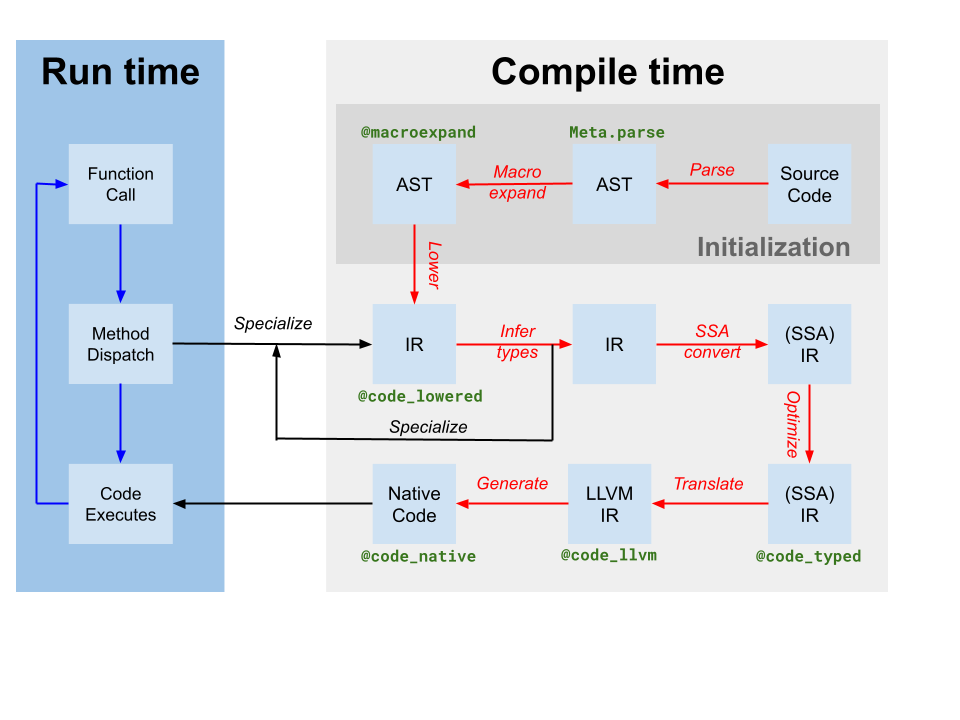

Основные этапы работы с кодом в **julia **на этой картинке следующие:

- **Парсинг**  - это преобразование исходных символов (**source code**) в некоторую промежуточную форму, которая называется **AST** (abstract syntax tree), в этой форме развернуты элементы синтактического сахара

- В **julia** дальше следует развертывание макросов, в матлабе, насколько я понимаю макросов нет (по крайней мере они не доступны), так или иначе, код пробразуется в некоторую промежуточную форму **IR **(intermediate representation),  в этой форме язык не знает про типы. Далее проиходит ряд специфических для **julia**  преобразований и оптимизаций кода

- Слева показана работа в **run-time** при вызове функции, вначале проиходит выбор метода **method dispatch, **то есть необходимо понять какой метод использовать, в **julia** выбор метода производится в зависимости от типа (типов) аргумента, в **матлабе** выбор метода производится по имени функции (и по типу первого аргумента, если это метод класса).

- И далее есть два пути стрелкой вниз показан путь для ситуации когда для функции с данным набором типов уже создан метод (хранится в кэше), если такой метод есть вызывается он. Стрелкой **specialize** показано, путь когда такая функций ранее не вызывалась, тогда мы идем по большому кругу, необходимо прогнать run-type типы данных через серию преобразований, чтобы получить в конце концов **native code** (что-то близкое к ассемблеру). Таким образом, информация о типах берется из текущих типов переменных, но **JIT **компилятор применяет информацию о типах не непосредственно на исходном коде в символьной записи, а уже на некоторйо промежуточной форме кода.

К сожалению, для матлаб такой схемы у меня нет, интересно было бы посмотреть как работает **JIT **в матлаб. 

### Функция eval

Парсинг и выполнение кода

eval("A+B") %

Error using eval
Unrecognized function or variable 'B'.

A=5;B=6;
eval("A+B")

ans = 11

A="A";B="B";
eval("A+B")

ans = "AB"

C = "Very important variable"

C = "Very important variable"

eval("C=rand(100)") % выполнение eval  - заменяет переменную

C =     0.5082    0.6216    0.4188    0.2509    0.2137    0.6825    0.7186    0.8290    0.2616    0.2016    0.6705    0.5306    0.1462    0.3755    0.4601    0.9300    0.6811    0.7284    0.2706    0.3766    0.3714    0.3933    0.6680    0.4947    0.5387    0.8807    0.5124    0.2087    0.8269    0.1871    0.4427    0.4067    0.0483    0.1356    0.2179    0.3885    0.6175    0.0626    0.8428    0.6899    0.0069    0.2889    0.8330    0.4261    0.4409    0.0067    0.4236    0.7410    0.8100    0.9111
    0.6128    0.4285    0.3976    0.9319    0.2811    0.2788    0.5004    0.1384    0.7522    0.1063    0.8253    0.2403    0.8863    0.9790    0.2866    0.5429    0.0880    0.4287    0.8710    0.9041    0.5456    0.7462    0.2481    0.6159    0.5821    0.3287    0.6950    0.3601    0.1215    0.2630    0.0898    0.2259    0.0618    0.0148    0.1305    0.3909    0.7292    0.0377    0.2760    0.8090    0.4523    0.9149    0.2905    0.5666    0.5564    0.7208    0.2455    0.3342    0.8426    0

N = randi(500)

N = 457

fun = @()eval("rand("+string(N)+")");% это анонимная функция, про них - дальше

disp("Вызов  функции через eval: ")

Вызов  функции через eval: 


timeit(fun)

ans = 0.0012

N_string = string(N);
disp("Вызов функции с аргументом, вычисляемым через  eval: ")

Вызов функции с аргументом, вычисляемым через  eval: 


timeit(@()rand(eval(N_string)))

ans = 0.0011

disp("Непосредственный вызов функции с числовым аргументом без eval: ")

Непосредственный вызов функции с числовым аргументом без eval: 


timeit(@()rand(N))

ans = 0.0011

Итого, как правило, eval  - медленнее, чем вызов функции непосредствено, кроме того, использование eval приводит к меньшей прозрачности кода (см. пример с заменой переменной)

## Выводы по семинару 5 

- Функции для работы с файловой системой **cd**() - поменять текущую директорию, **pwd**() - запросить текущуб папку

- **Workspace** - пространство имен переменных и соответсвующего им содержимого в памяти в текущий момент времени. Функции **who**()  - имена переменных, **whos**() - информация о переменных. При старте матлаб, комнадная строка работает с  базовым **workspace** - **base**

- Прежде, чем быть выполненным текст программы  преобразуется и оптимизируется, окончательно инструкции "железу" формируются когда понятна типизация переменных, которая получается в режиме **run-time. **Алгоритм работы JIT в матлаб толком не понятен (документации на него нет), поэтому лучше всего, если нужен  

ПЕРЕД ВЫХОДОМ - ЗАПУСТИТЬ ЭТУ ЯЧЕЙКУ, ЧТОБЫ ПОЧИСТИТЬ ВРЕМЕННЫЕ ПАПКИ (УДАЛЯЮТСЯ ВСЕ ПАПКИ, ЛЕЖАЩИЕ В КОРНЕВОМ КАТАЛОГЕ КРОМЕ "**pdfs**")

dir_Struct = dir(get_folder());
is_dir = arrayfun(@(X)X.isdir,dir_Struct);
if any(is_dir)
    dir_Struct = dir_Struct(is_dir);
    folders_to_remove_names = arrayfun(@(X)string(X.name),dir_Struct);
    folders_to_remove_names = folders_to_remove_names(:);
    is_dir = folders_to_remove_names==["." ".." "pdfs"];
    is_dir = ~any(is_dir,2);
    if ~any(is_dir)
        clearvars
        return
    end
    dir_Struct = dir_Struct(is_dir);
    full_dirs = arrayfun(@(X) string(fullfile(X.folder,X.name)),dir_Struct);
    full_dirs = transpose(full_dirs(:));
    for d = full_dirs
        rmpath(d);
        rmdir(d,'s');
    end
end

Error using rmdir
E:\projects\matlab-seminar\basics\sem5_6\temp could not be removed.

ДАЛЬШЕ ИДЕТ БЛОК ФУНКЦИЙ

function folder = get_folder()
% функция смотрит какой файл открыт в редакторе в настоящий момент и
% возвращает путь к данному файлу
    folder = fileparts(matlab.desktop.editor.getActiveFilename);
end
function make_script(folder,name,varargin)
% функция создает текст скриптов и пишетего в файл
    arguments
        folder (1,1) string
        name (1,1) string
    end
    arguments (Repeating)
        varargin string
    end
    % формируем текст скрипта
        script1_text = string(varargin); % не будем пользоваться матлабовским редактором файлов, так как он "слишком умный"
        if ~isfolder(folder)
            mkdir(folder)
        end
        % пишем текст скрипта в файл
        writelines(script1_text,fullfile(folder,name + ".m"));
end
function make_function(folder,name,input_args,output_args,varargin)
% функция создает текст функции и пишет его в файл
    arguments
        folder (1,1) string
        name (1,1) string
        input_args string
        output_args string
    end
    arguments (Repeating)
        varargin string
    end
    argin = cell(1,2+ numel(varargin));
    head = "function ";
    if ~isempty(output_args)
        head = head + "[" + join(output_args,",") + "] = ";
    end
    head =head + name;
    if isempty(input_args)
        head = head +"()";
    else
        head = head +"(" + join(input_args,",")+")";
    end
    argin{1} = head;
    argin(2:end-1) = varargin;
    argin{end} = "end";
    % формируем текст скрипта
    fun_text = string(argin); % не будем пользоваться матлабовским редактором файлов, так как он "слишком умный"
    if ~isfolder(folder)
        mkdir(folder)
    end
    % пишем текст скрипта в файл
    writelines(fun_text,fullfile(folder,name + ".m"));
end
function code = read_code(fun_name)
    switch class(fun_name)
        case "string"
            filename = functions(str2func(fun_name)).file;
        case "function_handle"
            filename = functions(fun_name).file;
        otherwise
            code = '';
            return
    end
    if isempty(filename)
        code = fun_name;
        return 
    end
    code = string(fileread(filename));
end
function varargout = vararargout_function(varargin)
    % varargout  - тоже особое слово, в теле функции оно означает, что
    % данный массив ячеек возвращается как splat - функции
    disp(['Число входных аргументов: ' num2str(nargin)]);
    disp(['Число вЫходных аргументов: ' num2str(nargout)]);
    
    number_output_arguments = nargout; % особое слово, чтобы узнать число выходных аргументов, находясь фнутри функции
    varargout = cell(1,number_output_arguments);
    for counter=1:numel(varargin)
        if counter>number_output_arguments
            return
        else
            varargout{counter}=svds(varargin{counter});
        end
    end       
end
function out = ignore_arguments(x,~,~)
    out = sin(x);
end
function no_ignore_arguments(x,y,z) % аргументы фигурируют, но не игнорируются
    out = sin(x);
end
function [A,B] = call_handle(A,B,fun_handle)
    [A,B] = fun_handle(A,B);
end
function [A,B,nested_fun_handle] = external_fun(A,B)
     who
    nested_fun() % вызов вложенной функции (может быть в любом месте, вложенная функция - не скрипт!
    function nested_fun() % объявление вложенной функции
        disp("workspace вложенной функции")
        who % почему не работает второй ху?
        [A,B] = swap(A,B); % переменные во внешней функции для вложенной функции являются глобальными
    end
    nested_fun_handle = @nested_fun;
end
function [A,B] =multi_embedded_fun(A,B)
    embedded_fun()
    function embedded_fun()
        embedded_fun()
        function embedded_fun()
            embedded_fun()
            function embedded_fun()
                embedded_fun()
                function embedded_fun()
                    embedded_fun()
                    function embedded_fun()
                        embedded_fun()
                        function embedded_fun()
                            who
                            [A,B] = swap(A,B);
                        end 
                    end 
                end 
            end 
        end 
    end 
end
function out = annotated_arguments(A,B,C)
    arguments 
        A (1,1) {mustBeInteger,mustBePositive} % означает, что аргументы должен быть целым
        B (1,:) double % дополнительно указан тип аргумента, также размерность указана частично!
        C (1,1) string {mustBeMember(C,["sin" "cos" "tan"])} ="sin" % 
    end
    out = repmat(transpose(B),[1 A]);
    fun_handle = str2func(C);
    for i = 2:A
        out(:,i) = fun_handle(out(:,i-1));
    end
end
% function out = name_value_pairs(options)
% % Важно при написании функций делать к ним хорошую документацию. 
% % Блок arguments можно рассматривать как часть документации, так как информация о типах, 
% % структуре и области определения входных аргументов функции многое говорит о функции
%     arguments 
%         options.A (1,1) {mustBeInteger,mustBePositive} = 3 % означает, что аргументы должен быть целым
%         options.B (1,:) double = linspace(-pi,pi,100) % дополнительно указан тип аргумента, также размерность указана частично!
%         options.C (1,1) string {mustBeMember(options.C,["sin" "cos" "tan"])} ="sin" % 
%     end
%     out = repmat(transpose(options.B),[1 options.A]);
%     fun_handle = str2func(options.C);
%     for i = 1:A
%         out = fun_handle(out);
%     end
% end
function C = input_expression(expression)
    C = eval(expression);
    whos
    caller_killer()
    whos 
end
function caller_killer()
    evalin('caller','clearvars');
end

function C = assign_in_function(expression)
    C = eval(expression);
    whos
    assignin_internal_fun()
    whos 
end
function assignin_internal_fun()
    evalin('caller','C=pi');
end
function [y,p] = persistent_func(f,dx)
% функция сдвигает фазу аргумента функции f на величину dx
    persistent x
    persistent animated_Line axes_handle; % при первом пуске persistent переменная []
    if isempty(x)
        x =-dx; % обнуляем сдвиг в начальный момент
    end
    if isempty(animated_Line)
        axes_handle = axes(figure(10),"XTickMode","manual","YTickMode","manual","XLim",[0,2*pi],"YLim",[-1 1]);
        animated_Line = animatedline(axes_handle,"Marker","o","LineStyle","none");
    end
    x=x+dx;
    y = f(x);
    addpoints(animated_Line,x,y);
    drawnow  
end
function out = repeating_name_value_pairs(name,value)
% Важно при написании функций делать к ним хорошую документацию. 
% Блок arguments можно рассматривать как часть документации, так как информация о типах, 
% структуре и области определения входных аргументов функции многое говорит о функции
    arguments (Repeating)
        name (1,1) string  % означает, что аргументы должен быть целым
        value (1,:) double  % дополнительно указан тип аргумента, также размерность указана частично!
    end
    out = cellstr(name) + "=" + string(cell2mat(value));
end
function out = exist_check_fun(A,B,C)
% функция exist(variable_name,"var") проверяет существует ли переменная с именем variable_name
out = 0;
    if exist('A','var')
            out = out + A;
    end
    if exist('B','var')
            out = out + B;
    end
    if exist('C','var')
            out = out + C;
    end
end
function on_clean_up_check(expr,f_handle)
    on_clean_up_obj = onCleanup(f_handle);
    eval(expr);
    pause(5)
    
end
function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end